t_vis=1:24

t_vis =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24


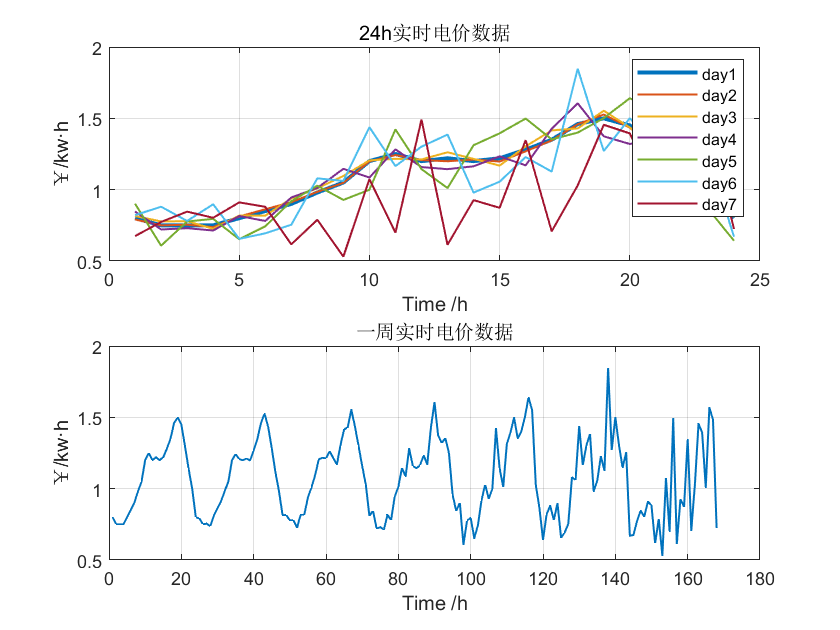

figure(1)
subplot(2,1,1)
plot(t_vis,p_daily(1,:),'LineWidth',2)
grid on
hold on
plot(t_vis,p_daily(2,:),'LineWidth',1)
plot(t_vis,p_daily(3,:),'LineWidth',1)
plot(t_vis,p_daily(4,:),'LineWidth',1)
plot(t_vis,p_daily(5,:),'LineWidth',1)
plot(t_vis,p_daily(6,:),'LineWidth',1)
plot(t_vis,p_daily(7,:),'LineWidth',1)
xlabel('Time /h')
ylabel('￥/kw·h')
title('24h实时电价数据')
legend('day1','day2','day3','day4','day5','day6','day7')

subplot(2,1,2)

t_conti=1:n-1;
plot(t_conti,price,'LineWidth',1)
grid on
xlabel('Time /h')
ylabel('￥/kw·h')
title('一周实时电价数据')

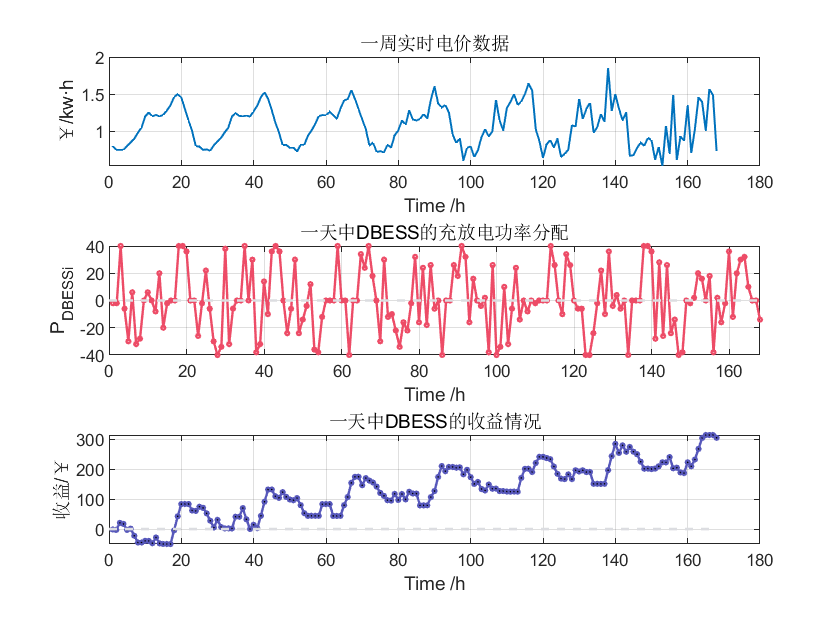



figure(2)
subplot(3,1,1)
plot(t_conti,price,'LineWidth',1)
grid on
xlabel('Time /h')
ylabel('￥/kw·h')
title('一周实时电价数据')

subplot(3,1,2)
plot(t_conti,P_conti,'LineWidth',1.2,'Color','#ED4C67','Marker',"o","MarkerSize",2);
hold on
line([0,168],[0,0],"Color",'#dcdde1',"LineWidth",1.3,'LineStyle','--')
grid on
xlabel('Time /h')
ylabel('P_{DBESS}_i')
title('一天中DBESS的充放电功率分配')
axis([0,168,-P_N,P_N])

subplot(3,1,3)
plot(t_conti,gain_vis(1,:),'LineWidth',1.2,'Color','#5758BB','Marker',"o","MarkerSize",2,"MarkerFaceColor",'k');
hold on
line([0,168],[0,0],"Color",'#dcdde1',"LineWidth",1.3,'LineStyle','--')
grid on
xlabel('Time /h')
ylabel('收益/￥')
title('一天中DBESS的收益情况')